## Kalman Filter with Linear System Model

In this example we use Kalman filter on a linear discrete system model identified with System Identification Toolbox, of the following form:

- The C term is the measurement matrix which maps system state to system output.

- The D term is a matrix that maps that system input to immediate system output. This is often zero because most systems are not instantly affected by input.

- The *e* term represents disturbance or noise: anything "unexplained" that causes the output of the system model not to match the real system. You don't need to include this term in the filter unless you have a way to measure it. Since the *K* term is only used as the factor for *e* we can omit that as well.

- The *A* and *B* terms are the State and Input transition matrices, respectively. *A* encodes the information that will advance the system state based on the previous state, and *B* encodes the information that will advance the system state based on input to the system.

The System Identification Toolbox also provides the constants *x0*, *dx0* and *NoiseVariance* for systems it identifies:

- x0 is initial state. This is based on the specific data set used to "train" the system.

- dx0 is the standard deviation (uncertainty) of each system state variable.

- NoiseVariance is the variance of process noise or disturbance. This can be projected onto the Q matrix to represent the uncertainty of system output.

### Filter

Below we implement the identified system as a vectorized function and use it to filter the same data set the system was trained on.

Observe how tuning the model uncertainty will change the behavior of the filter to trust the model more or the trust the measurements more.

file = readmatrix("/Users/valeriynovytskyy/Desktop/kalman/input.csv");
time = file(:,1);
measurements = file(:, 2);
inputs = file(:, 3);

noiseVariance = 1e-10

noiseVariance = 1.0000e-10

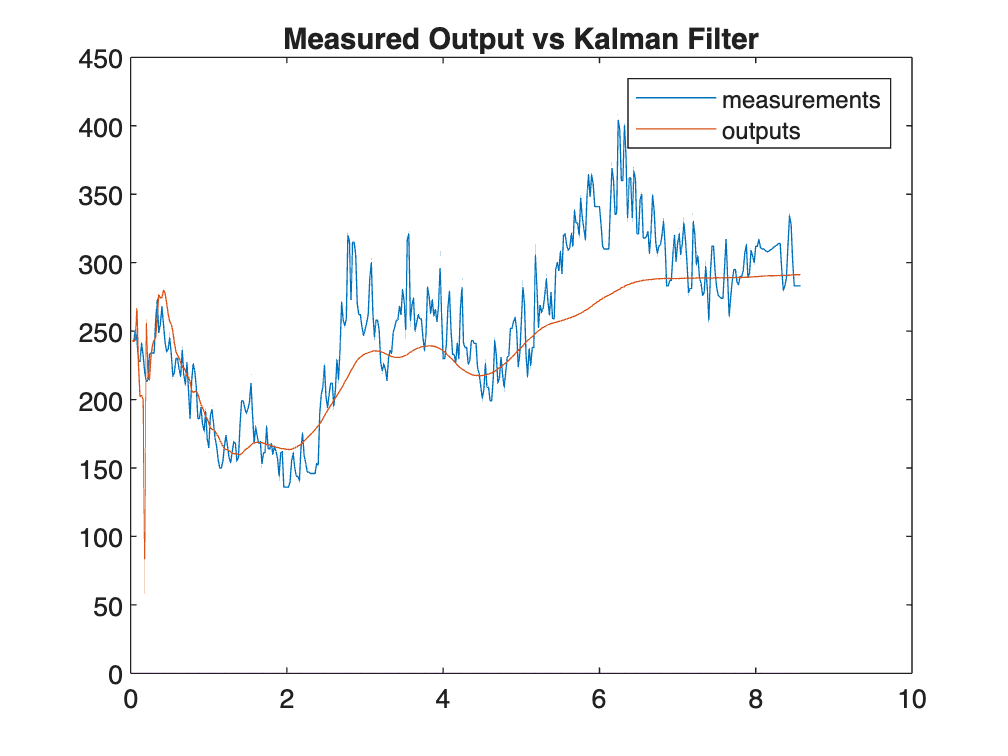


[outputs, gains] = kalmanFilter( ...
    measurements, ...
    inputs, ...
    noiseVariance ...
);

plot(time, measurements, time, outputs);
legend('measurements', 'outputs');
title('Measured Output vs Kalman Filter');

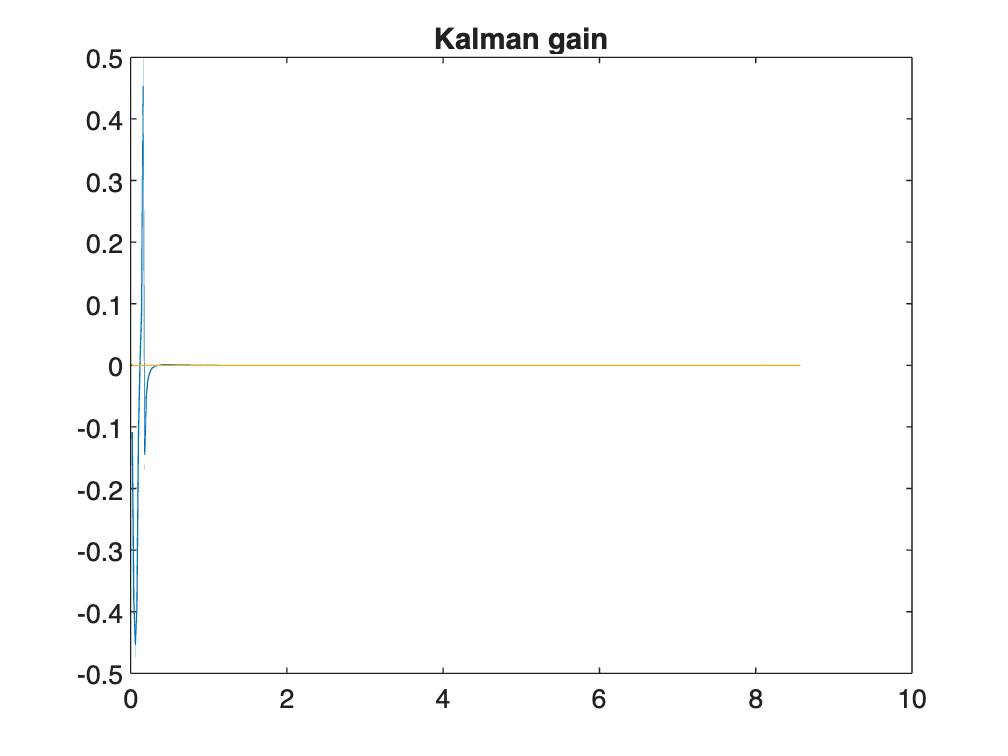


plot(time, gains)
title('Kalman gain')

function [outputs, gains] = kalmanFilter( ...
    measurements, ...
    inputs, ...
    noiseVariance ...
)
    % Pre-allocate arrays
    outputs = zeros(length(measurements));
    gains = zeros(length(measurements));

    % A weights (3x3 matrix)
    A = [ ...
      1.0005, -0.0050, 0.0001;
      0.0061, 0.9881, -0.0684;
      -0.0009, 0.0768, 0.9224;
    ];
    
    % B weights (3x1 vector)
    B = [ ...
      8.7913e-10;
      1.0489e-07;
      -2.4853e-05;
    ];
    
    % C weights (1x3 vector)
    C = [ ...
      -5.2908e+03, ...
      13.0803, ...
      -0.6389 ...
    ];
    
    % D weight (scalar)
    D = 0;
    
    % Initial state (3x1 vector)
    x0 = [ ...
      -0.0461;
      -0.0198;
      0.0098;
    ];

    % Initial state standard deviation (3x1 vector)
    dx0 = [ ...
      7.4356e+06;
      3.9306e+09;
      5.1495e+10;
    ];

    % Initial covariance
    P0 = diag(dx0.^2);

    % State identity matrix
    I = eye(length(x0));

    % Noise covariance (projected from noise variance)
    Q = I * noiseVariance;

    % Measurement variance
    R = var(measurements);

    % Initialize state
    x = x0;

    % Initialize covariance
    P = P0;

    for i = 1:length(inputs)
        % Input
        u = inputs(i);
        z = measurements(i);
        
        % Update state
        x = A * x + B * u;

        % Predict
        prediction = C * x + D * u;

        % Update covariance
        P = A * P * A' + Q;
    
        % Optimize gain
        K = (P * C') / (C * P * C' + R);

        % Correct state with measurement
        x = x + K * (z - prediction);

        % Correct covariance
        P = (I - K * C) * P * (I - K * C)' + K * R * K';

        % Output
        outputs(i) = prediction;
        gains(i) = sum(K);
    end
end